# Measuring Planar Objects with a Calibrated Camera

This example shows how to measure the diameter of coins in world units using a single calibrated camera.

## Overview

This example shows how to calibrate a camera, and then use it to measure the size of planar objects, such as coins. An example application of this approach is measuring parts on a conveyor belt for quality control.

## Calibrate the Camera

Camera calibration is the process of estimating the parameters of the lens and the image sensor. These parameters are needed to measure objects captured by the camera. This example shows how to calibrate a camera programmatically. Alternatively, you can calibrate a camera using the [`cameraCalibrator`](docid:vision_ug#btxr8c_-1) app.

To calibrate the camera, we first need to take multiple images of a calibration pattern from different angles. A typical calibration pattern is an asymmetric checkerboard, where one side contains an even number of squares, both black and white, and the other contains an odd number of squares. 

The pattern must be affixed to a flat surface, and it should be at approximately the same distance from the camera as the objects you want to measure. The size of a square must be measured in world units, for example millimeters, as precisely as possible. In this example we use 9 images of the pattern, but in practice it is recommended to use 10 to 20 images for accurate calibration.

## Prepare Calibration Images

Create a cell array of file names of calibration images.

% 이미지가 저장된 경로를 지정 (예: C 드라이브의 특정 폴더 경로)
imageFolder = '/MATLAB Drive/Examples/R2024a/vision/MeasuringPlanarObjectsExample';

% 해당 폴더 내의 모든 PNG 파일을 가져오기
imageFiles = dir(fullfile(imageFolder, '*.png'));

% 이미지 개수 확인
numImages = length(imageFiles);
%print(numImages);
files = cell(1, numImages);

% 이미지 파일 경로 저장
for i = 1:numImages
    files{i} = fullfile(imageFolder, imageFiles(i).name);
end

% 첫 번째 이미지를 불러와서 출력
magnification = 25;
I = imread(files{1});
figure; imshow(I, 'InitialMagnification', magnification);

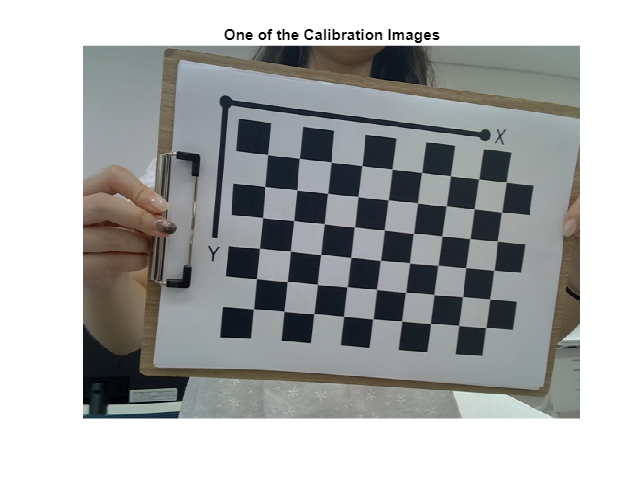

title("One of the Calibration Images");

## Estimate Camera Parameters

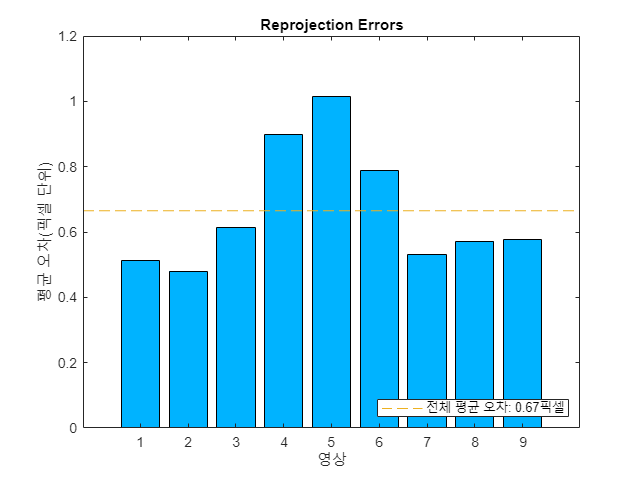

% Detect the checkerboard corners in the images.
[imagePoints, boardSize] = detectCheckerboardPoints(files);

% Generate the world coordinates of the checkerboard corners in the
% pattern-centric coordinate system, with the upper-left corner at (0,0).
squareSize = 22.5; % in millimeters
worldPoints = generateCheckerboardPoints(boardSize, squareSize);

% Calibrate the camera.
imageSize = [size(I, 1), size(I, 2)];
cameraParams = estimateCameraParameters(imagePoints, worldPoints, ...
                                     ImageSize = imageSize);

% Evaluate calibration accuracy.
figure; showReprojectionErrors(cameraParams);
title("Reprojection Errors");

The bar graph indicates the accuracy of the calibration. Each bar shows the mean reprojection error for the corresponding calibration image. The reprojection errors are the distances between the corner points detected in the image, and the corresponding ideal world points projected into the image.

cameraParams

cameraParams =   cameraParameters - 속성 있음:

   Camera Intrinsics
                         Intrinsics: [1x1 cameraIntrinsics]

   Camera Extrinsics
                  PatternExtrinsics: [9x1 rigidtform3d]

   Accuracy of Estimation
              MeanReprojectionError: 0.6654
                 ReprojectionErrors: [54x2x9 double]
                  ReprojectedPoints: [54x2x9 double]

   Calibration Settings
                        NumPatterns: 9
                  DetectedKeypoints: [54x9 logical]
                        WorldPoints: [54x2 double]
                         WorldUnits: 'mm'
                       EstimateSkew: 0
    NumRadialDistortionCoefficients: 2
       EstimateTangentialDistortion: 0


% Camera Intrinsics
disp('--- Camera Intrinsics ---');

--- Camera Intrinsics ---


disp(cameraParams.Intrinsics);  % 카메라 내재 파라미터

  cameraIntrinsics - 속성 있음:

             FocalLength: [515.8456 510.8645]
          PrincipalPoint: [224.2397 215.6325]
               ImageSize: [480 640]
        RadialDistortion: [-0.1004 -0.0059]
    TangentialDistortion: [0 0]
                    Skew: 0
                       K: [3x3 double]



% Camera Extrinsics
disp('--- Camera Extrinsics ---');

--- Camera Extrinsics ---


disp(cameraParams.PatternExtrinsics);  % 외재 파라미터

  9x1 rigidtform3d 배열 - 속성 있음:

    Dimensionality
    Translation
    R
    A




% Accuracy of Estimation
disp('--- Accuracy of Estimation ---');

--- Accuracy of Estimation ---


disp(['Mean Reprojection Error: ', num2str(cameraParams.MeanReprojectionError)]);

Mean Reprojection Error: 0.66539


disp('Reprojection Errors:');

Reprojection Errors:


disp(cameraParams.ReprojectionErrors);  % 재투영 오차


(:,:,1) =

    0.6351    1.3904
    0.3138    0.4127
   -0.0441    0.0681
   -0.3339   -0.0990
   -0.6429   -0.3408
   -0.8942   -0.7084
    0.0898    0.8970
    0.0066    0.1706
   -0.1836    0.0893
   -0.4342    0.0515
   -0.8056   -0.0691
   -1.0876   -0.1715
    0.0883    0.4702
    0.1987   -0.0587
    0.1767   -0.0531
   -0.0101   -0.0261
   -0.3875    0.1108
   -0.6384    0.1817
   -0.1179    0.1572
    0.2816   -0.2868
    0.3408   -0.1808
    0.1961   -0.1191
    0.0326    0.1757
   -0.3406    0.2280
   -0.3006    0.0779
    0.2107   -0.3838
    0.3974   -0.3103
    0.3759   -0.1223
    0.1581    0.1628
   -0.2532    0.1682
   -0.2474    0.0376
    0.3461   -0.3537
    0.6915   -0.3069
    0.6897   -0.1789
    0.4441   -0.0294
   -0.0377   -0.0114
   -0.3534    0.1362
    0.4498   -0.2869
    0.8375   -0.1701
    0.8261   -0.1333
    0.5318   -0.0215
   -0.1123   -0.2367
   -0.7441    0.3538
    0.3612   -0.1259
    0.7874   -0.0724
    0.7199   -0.0806
    0.3693   -0.0315
 

disp('Reprojected Points:');

Reprojected Points:


disp(cameraParams.ReprojectedPoints);  % 재투영된 점들


(:,:,1) =

  240.1284  143.0168
  235.9602  182.9687
  231.8029  222.7180
  227.6717  262.1206
  223.5813  301.0392
  219.5456  339.3422
  280.3169  147.2383
  276.0609  187.0908
  271.7665  226.7372
  267.4507  266.0341
  263.1298  304.8445
  258.8191  343.0376
  320.2066  151.5212
  315.8709  191.2249
  311.4474  230.7204
  306.9552  269.8645
  302.4119  308.5208
  297.8342  346.5585
  359.6489  155.8500
  355.2438  195.3559
  350.7013  234.6528
  346.0422  273.5976
  341.2859  312.0542
  336.4506  349.8917
  398.4957  160.2097
  394.0335  199.4690
  389.3836  238.5199
  384.5690  277.2192
  379.6108  315.4305
  374.5282  353.0230
  436.5975  164.5857
  432.0927  203.5496
  427.3493  242.3071
  422.3922  280.7144
  417.2442  318.6351
  411.9262  355.9378
  473.8031  168.9633
  469.2723  207.5830
  464.4510  245.9994
  459.3662  284.0683
  454.0423  321.6527
  448.5021  358.6208
  509.9584  173.3279
  505.4206  211.5542
  500.5391  249.5816
  495.3431  287.2654
  489.8589  324.4675
 


% Calibration Settings
disp('--- Calibration Settings ---');

--- Calibration Settings ---


disp(['Number of Patterns: ', num2str(cameraParams.NumPatterns)]);

Number of Patterns: 9


disp('Detected Keypoints:');

Detected Keypoints:


disp(cameraParams.DetectedKeypoints);  % 검출된 키포인트

   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1
 

disp('World Points:');

World Points:


disp(cameraParams.WorldPoints);  % 월드 좌표계의 체커보드 코너 좌표

         0         0
         0   22.5000
         0   45.0000
         0   67.5000
         0   90.0000
         0  112.5000
   22.5000         0
   22.5000   22.5000
   22.5000   45.0000
   22.5000   67.5000
   22.5000   90.0000
   22.5000  112.5000
   45.0000         0
   45.0000   22.5000
   45.0000   45.0000
   45.0000   67.5000
   45.0000   90.0000
   45.0000  112.5000
   67.5000         0
   67.5000   22.5000
   67.5000   45.0000
   67.5000   67.5000
   67.5000   90.0000
   67.5000  112.5000
   90.0000         0
   90.0000   22.5000
   90.0000   45.0000
   90.0000   67.5000
   90.0000   90.0000
   90.0000  112.5000
  112.5000         0
  112.5000   22.5000
  112.5000   45.0000
  112.5000   67.5000
  112.5000   90.0000
  112.5000  112.5000
  135.0000         0
  135.0000   22.5000
  135.0000   45.0000
  135.0000   67.5000
  135.0000   90.0000
  135.0000  112.5000
  157.5000         0
  157.5000   22.5000
  157.5000   45.0000
  157.5000   67.5000
  157.5000   90.0000
  157.5000  1

disp(['World Units: ', cameraParams.WorldUnits]);  % 단위 (예: 'mm')

World Units: mm


disp(['Estimate Skew: ', num2str(cameraParams.EstimateSkew)]);

Estimate Skew: 0


disp(['Number of Radial Distortion Coefficients: ', num2str(cameraParams.NumRadialDistortionCoefficients)]);

Number of Radial Distortion Coefficients: 2


disp(['Estimate Tangential Distortion: ', num2str(cameraParams.EstimateTangentialDistortion)]);

Estimate Tangential Distortion: 0


## Read the Image of Objects to Be Measured

Load the image containing objects to be measured. This image includes the calibration pattern, and the pattern is in the same plane as the objects you want to measure. In this example, both the pattern and the coins are on the same table top. 

Alternatively, you could use two separate images: one containing the pattern, and the other containing the objects to be measured. Again, the objects and the pattern must be in the same plane. Furthermore, images must be captured from exactly the same view point, meaning that the camera must be fixed in place.

imOrig = imread(fullfile(matlabroot, "toolbox", "vision", "visiondata", ...
        "calibration", "slr", "image9.jpg"));
figure; imshow(imOrig, InitialMagnification = magnification);

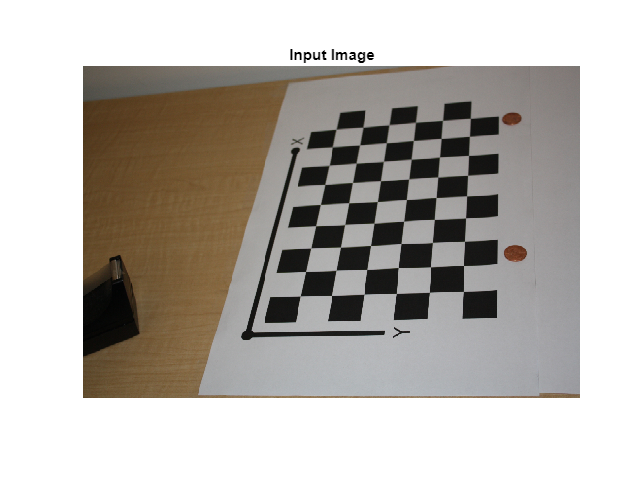

title("Input Image");

## Undistort the Image

Use the cameraParameters object to remove lens distortion from the image. This is necessary for accurate measurement. 

% Since the lens introduced little distortion, use 'full' output view to illustrate that
% the image was undistored. If we used the default 'same' option, it would be difficult
% to notice any difference when compared to the original image. Notice the small black borders.
[im, newOrigin] = undistortImage(imOrig, cameraParams, OutputView = "full");

다음 사용 중 오류가 발생함: vision.internal.inputValidation.checkImageSize (14번 라인)
영상 크기가 카메라 내부 파라미터와 일치하지 않습니다. 이 영상이 지정된 카메라에서 생성되지 않은 것일 수 있습니다.

오류 발생: undistortImage (14번 라인)
vision.internal.inputValidation.checkImageSize(I, intrinsics.ImageSize);

figure; imshow(im, InitialMagnification = magnification);
title("Undistorted Image");

Note that this image exhibits very little lens distortion. The undistortion step is far more important if you use a wide-angle lens, or a low-end webcam.

## Segment Coins

In this case, the coins are colorful on white background. Use the saturation component of the HSV representation of the image to segment them out.

% Convert the image to the HSV color space.
imHSV = rgb2hsv(im);

% Get the saturation channel.
saturation = imHSV(:, :, 2);

% Threshold the image
t = graythresh(saturation);
imCoin = (saturation > t);

figure; imshow(imCoin, InitialMagnification = magnification);
title("Segmented Coins");

## Detect Coins

We can assume that the two largest connected components in the segmented image correspond to the coins.

% Find connected components.
blobAnalysis = vision.BlobAnalysis(AreaOutputPort = true,...
    CentroidOutputPort = false,...
    BoundingBoxOutputPort = true,...
    MinimumBlobArea = 200, ExcludeBorderBlobs = true);
[areas, boxes] = step(blobAnalysis, imCoin);

% Sort connected components in descending order by area
[~, idx] = sort(areas, "Descend");

% Get the two largest components.
boxes = double(boxes(idx(1:2), :));

% Reduce the size of the image for display.
scale = magnification / 100;
imDetectedCoins = imresize(im, scale);

% Insert labels for the coins.
imDetectedCoins = insertObjectAnnotation(imDetectedCoins, "rectangle", ...
    scale * boxes, "penny");
figure; imshow(imDetectedCoins);
title("Detected Coins");

## Compute Extrinsics

To map points in the image coordinates to points in the world coordinates we need to compute the rotation and the translation of the camera relative to the calibration pattern. Note that the `estimateExtrinsics` function assumes that there is no lens distortion. In this case imagePoints have been detected in an image that has already been undistorted using [`undistortImage`](docid:vision_ref#btyx3m1-1).

% Detect the checkerboard.
[imagePoints, boardSize] = detectCheckerboardPoints(im);

% Adjust the imagePoints so that they are expressed in the coordinate system
% used in the original image, before it was undistorted.  This adjustment
% makes it compatible with the cameraParameters object computed for the original image.
imagePoints = imagePoints + newOrigin; % adds newOrigin to every row of imagePoints

% Extract camera intrinsics.
camIntrinsics = cameraParams.Intrinsics;

% Compute extrinsic parameters of the camera.
camExtrinsics = estimateExtrinsics(imagePoints, worldPoints, camIntrinsics);

## Measure the First Coin

To measure the first coin we convert the top-left and the top-right corners of the bounding box into world coordinates. Then we compute the Euclidean distance between them in millimeters. Note that the actual diameter of a US penny is 19.05 mm.

% Adjust upper left corners of bounding boxes for coordinate system shift 
% caused by undistortImage with output view of 'full'. This would not be
% needed if the output was 'same'. The adjustment makes the points compatible
% with the cameraParameters of the original image.
boxes = boxes + [newOrigin, 0, 0]; % zero padding is added for width and height

% Get the top-left and the top-right corners.
box1 = double(boxes(1, :));
imagePoints1 = [box1(1:2); ...
                box1(1) + box1(3), box1(2)];

% Get the world coordinates of the corners            
worldPoints1 = img2world2d(imagePoints1, camExtrinsics, camIntrinsics);

% Compute the diameter of the coin in millimeters.
d = worldPoints1(2, :) - worldPoints1(1, :);
diameterInMillimeters = hypot(d(1), d(2));
fprintf("Measured diameter of one penny = %0.2f mm\n", diameterInMillimeters);

## Measure the Second Coin

Measure the second coin the same way as the first coin.

% Get the top-left and the top-right corners.
box2 = double(boxes(2, :));
imagePoints2 = [box2(1:2); ...
                box2(1) + box2(3), box2(2)];

% Apply the inverse transformation from image to world            
worldPoints2 = img2world2d(imagePoints2, camExtrinsics, camIntrinsics);

% Compute the diameter of the coin in millimeters.
d = worldPoints2(2, :) - worldPoints2(1, :);
diameterInMillimeters = hypot(d(1), d(2));
fprintf("Measured diameter of the other penny = %0.2f mm\n", diameterInMillimeters);

## Measure the Distance to The First Coin

In addition to measuring the size of the coin, we can also measure how far away it is from the camera. 

% Compute the center of the first coin in the image.
center1_image = box1(1:2) + box1(3:4)/2;

% Convert to world coordinates.
center1_world  = img2world2d(center1_image, camExtrinsics, camIntrinsics);

% Remember to add the 0 z-coordinate.
center1_world = [center1_world 0];

% Compute the distance to the camera.
cameraPose = extr2pose(camExtrinsics);
cameraLocation = cameraPose.Translation;
distanceToCamera = norm(center1_world - cameraLocation);
fprintf("Distance from the camera to the first penny = %0.2f mm\n", ...
    distanceToCamera);

## Summary

This example showed how to use a calibrated camera to measure planar objects. Note that the measurements were accurate to within 0.2 mm.

## References

[1] Z. Zhang. A flexible new technique for camera calibration. IEEE Transactions on Pattern Analysis and Machine Intelligence, 22(11):1330-1334, 2000.

*Copyright 2013-2022 The MathWorks, Inc.*